% qmInfWellm

% QUANTUM MECHANICS
%  An electron in an infinitely deep square well 
%  Schrodinger Equation : eigenvalue and eigenfunctions
%  Spatial wavefunction
%  Binding energy spectrum

% Ian Cooper
% email: matlabvisualphysics@gmail.com
% 200425 / Matlab version R2020a

% DOING PHYSICS WITH MATLAB 
%    http://www.physics.usyd.edu.au/teach_res/mp/mphome.htm
% Reference page for documentation and notes
%    http://www.physics.usyd.edu.au/teach_res/mp/doc/qmPotential.htm
% Download Location
%    http://www.physics.usyd.edu.au/teach_res/mp/mscripts/
  

clear 
close all
clc


% INPUTS  =============================================================

% STATE: Principle Quantum Number  n = 1,2,3, ...  
  n = 2

n = 2

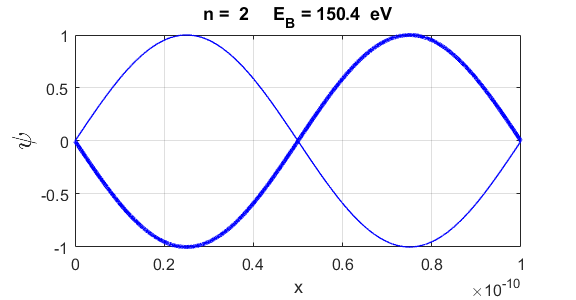


  
% Number of grid points
  N = 5599;
% Length of rod [m]
  L = 0.1e-9;
  
% CONSTANTS  ==========================================================
% Planck constant [ J.s] / Reduced Planck's constant
  h = 6.626070040e-34;            
  hbar = 1.054571800e-34; 
% Electron mass [kg] / electron charge  [C] 
  me = 9.10938356e-31; 
  e = 1.6021766208e-19;
  
  
% CALCULATIONS  ======================================================
% Spatial domain  [m]
  x = linspace(0,L,N+2);
  dx = x(2) - x(1);
  
% Eigenvalue Matrix A: eigenfunctions (eignFN) / eigenvalues (eignV) 
  off = ones(N-1,1);
  A = - diag(off,-1) + 2*eye(N) - diag(off,1) ;
  

  [eignFN, eignV] = eig(A);


 
% Spatial Wavefunction  psi
  psi = zeros(N+2,1);
  psi(2:N+1) = eignFN(:,n);
  psi = psi ./max(psi);

 
  
% Eigenvalue (coloumn vector)
  K = diag(eignV);
% Binding energy
  EB = K .* (hbar^2/(2*me*dx^2)/e); 

% GRAPHICS  ===========================================================  
figure(1)
  set(gcf,'units','normalized');
  set(gcf,'position',[0.02 0.1 0.30 0.25]);
  set(gcf,'color','w');
  
  plot(x,psi,'b','linewidth',3)
  hold on
  plot(x,-psi,'b','linewidth',1)
  grid on
  xlabel('x')
  txt = sprintf('n = %2.0f     E_B = %4.1f  eV',n,EB(n));
  title(txt)
  set(gca,'fontsize',12)
  ylabel('\psi','fontsize',20)

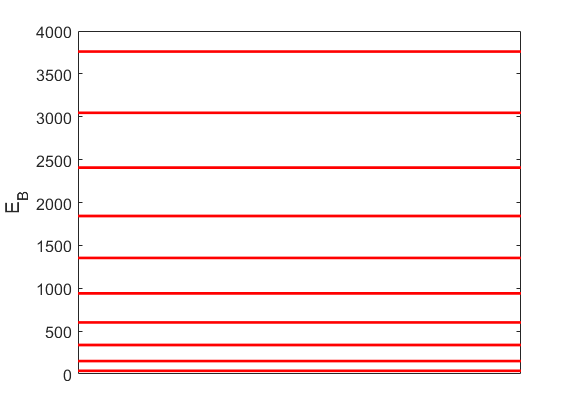

  
figure(2)
  set(gcf,'units','normalized');
  set(gcf,'position',[0.4 0.1 0.30 0.35]);
  set(gcf,'color','w');
  hold on
  
  for c = 1:10
   plot([0 L], [EB(c) EB(c)],'r','linewidth',2)
  end
  box on
  set(gca,'fontsize',12)
  ylabel('E_B','fontsize',14)
  set(gca, 'xtick', [-100 100]);